# Principal Component Analysis (PCA)

Lorem Ipsum

% add functions stored in an other path
addpath(genpath('../../functions'))

Farò uso della runzione `rand_between()` per generare valori casuali normalmente distribuiti tra due estremi.

% rand_between
% a: estremo inferiore
% b: estremo superiore
% n: numero di elementi da generare
% output: vettore
% function randbet = rand_between(a,b,n)
%     randbet = a + (b-a).*rand(n,1);
% end

% genero due distribuzioni

% ogni distribuzione conterrà n punti
n = 50;

% prima distribuzione
x = rand_between(2,6,n);
y = rand_between(1,3,n);
l = repelem(0,n,1);

% concateno i vettori x,y,l per popolarli con i punti della seconda
% distribuzione
x = [x;rand_between(1,4,50)];
y = [y; rand_between(3.5,5,n)];
l = [l; repelem(1,n,1)];

Per filtrare le x e le y appartenenti alla prima distribuzione mi basta usare la sintassi `x(l==0)` e `y(l==0)` che sta per "prendimi le righe che rispettano la condizione `l==0`". Procedo quindi a rappresentare queste due distribuzioni

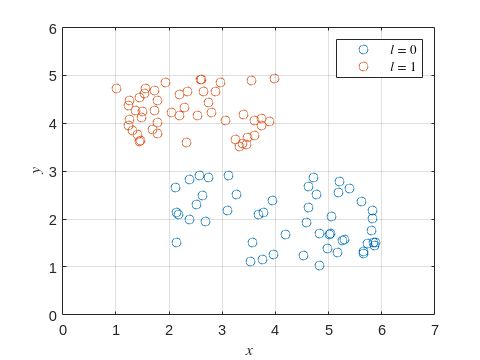

% rappresento la prima distribuzione
plot(x(l==0),y(l==0),'o')
hold on
% rappresento la seconda distribuzione
plot(x(l==1),y(l==1),'o')
hold off
xlim([0 7])
ylim([0 6])
grid on
legend("$l = 0$","$l = 1$",'Interpreter','latex')
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')

% calcolo media
xm = mean(x);
ym = mean(y);

% centro i dati
xc = x-xm;
yc = y-ym;

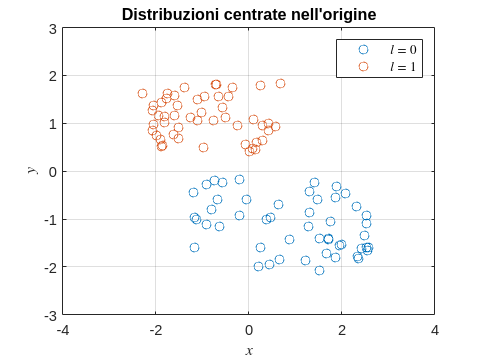

% plotto distribuzione centrata
plot(xc(l==0),yc(l==0),'o')
hold on
plot(xc(l==1),yc(l==1),'o')
hold off
xlim([-4 4])
ylim([-3 3])
grid on
legend("$l = 0$","$l = 1$",'Interpreter','latex')
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
title("Distribuzioni centrate nell'origine")

% esporto in md
livescript2markdown("pca.mlx","../README.md","AddMention",true)

Coverting latex to markdown is complete
README.md
Note: Related images are saved in README_images


ans = "/home/dennisangemi/Documenti/GitHub/machine-learning-for-physics/2_principal_component_analysis/README.md"